# Validacion de sistema

Comparativa planta no lineal con los datos experimentales. 

clear; clc; close all; 
load("../data/NLsysParams.mat"); % Importamos los datos de la planta

simout = sim("plantaV1.slx"); 

simout

simout =   Simulink.SimulationOutput:

            nl_response: [1x1 timeseries] 
                   tout: [1012x1 double] 
                   yout: [1x1 Simulink.SimulationData.Dataset] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 



t = simout.tout; 
y_nl = simout.nl_response.Data; 

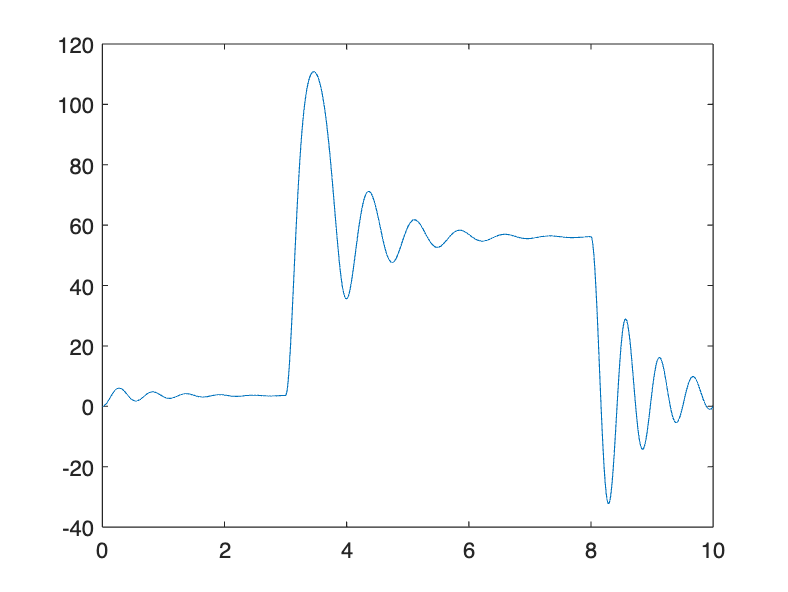

title("Comparativa"); 
plot(t, y_nl); 